# Asteroid Optical Navigation

ASEN 5044 Final Project Description

*Group Members: *James Monaco, AJ Cuddeback, Grant Kirchoff

## Part 1: Deterministic System Analysis

### 1. Nonlinear Simulation

run('sim_setup.m')
load orbitdetermination-finalproj_data_2023_11_14.mat



% solar radiation pressure 
a_SRP = -Phi_0 / norm(r_S)^2 * (1 + 4/9 * rho) * A_M * r_S / norm(r_S);

% non-linear simualtion
x_0 = [r_0_nom; dr_0_nom];
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));  % [s]
[t_ode45,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);

% plotting non-linear simulation solution
figure(1);
fig = tiledlayout(6,1)

f =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [6 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


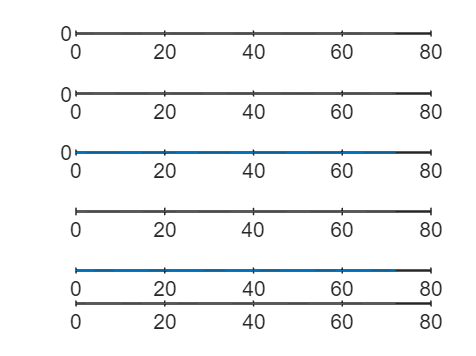

for i = 1:6
    nexttile(fig)
    plot(t_ode45/60/60,x_ode45(:,i))
end

### **2. Measurement Model**

Start with "fake" landmark at the center of the asteroid for a sanity check i.e., $l={\left\lbrack 0,0,0,\right\rbrack }^T$

r = x_ode45(:, 1:3)';

t_obs = unique(y_table(:,1));
steps = length(t_obs);

% start with centered landmark (l=0)
l = [0, 0, 0]';

for jj=1:steps
    RNC = R_CtoN(:, :, jj);
    [u, v] = measure(l, r(:, jj), RNC, u_0, v_0, f)
end

u = 551.3806

v = 421.4316

u = 552.0400

v = 421.6053

u = 552.5979

v = 421.7716

u = 553.0621

v = 421.9352

u = 553.4394

v = 422.1006

u = 553.7358

v = 422.2728

u = 553.9565

v = 422.4564

u = 554.1063

v = 422.6559

u = 554.1898

v = 422.8750

u = 554.2112

v = 423.1175

u = 554.1738

v = 423.3868

u = 554.0805

v = 423.6862

u = 553.9341

v = 424.0188

u = 553.7373

v = 424.3869

u = 553.4928

v = 424.7925

u = 553.2026

v = 425.2376

u = 552.8683

v = 425.7239

u = 552.4914

v = 426.2530

u = 552.0738

v = 426.8258

u = 551.6172

v = 427.4425

u = 551.1231

v = 428.1039

u = 550.5923

v = 428.8100

u = 550.0259

v = 429.5611

u = 549.4248

v = 430.3567

u = 548.7906

v = 431.1959

u = 548.1242

v = 432.0777

u = 547.4263

v = 433.0012

u = 546.6977

v = 433.9650

u = 545.9388

v = 434.9678

u = 545.1510

v = 436.0072

u = 544.3350

v = 437.0811

u = 543.4915

v = 438.1874

u = 542.6209

v = 439.3236

u = 541.7238

v = 440.4871

u = 540.8012

v = 441.6748

u = 539.8542

v = 442.8833

u = 538.8832

v = 444.1096

u = 537.8891

v = 445.3503

u = 536.8727

v = 446.6020

u = 535.8355

v = 447.8608

u = 534.7789

v = 449.1226

u = 533.7046

v = 450.3837

u = 532.6143

v = 451.6405

u = 531.5106

v = 452.8892

u = 530.3965

v = 454.1254

u = 529.2761

v = 455.3450

u = 528.1537

v = 456.5444

u = 527.0345

v = 457.7197

u = 525.9250

v = 458.8672

u = 524.8328

v = 459.9824

u = 523.7665

v = 461.0610

u = 522.7353

v = 462.0985

u = 521.7494

v = 463.0907

u = 520.8192

v = 464.0326

u = 519.9551

v = 464.9186

u = 519.1672

v = 465.7427

u = 518.4639

v = 466.4997

u = 517.8523

v = 467.1843

u = 517.3377

v = 467.7923

u = 516.9227

v = 468.3195

u = 516.6077

v = 468.7627

u = 516.3908

v = 469.1207

u = 516.2682

v = 469.3941

u = 516.2344

v = 469.5849

u = 516.2828

v = 469.6964

u = 516.4054

v = 469.7329

u = 516.5942

v = 469.7001

u = 516.8410

v = 469.6049

u = 517.1378

v = 469.4548

u = 517.4767

v = 469.2576

u = 517.8500

v = 469.0208

u = 518.2508

v = 468.7523

u = 518.6725

v = 468.4600

u = 519.1096

v = 468.1517

u = 519.5567

v = 467.8347

u = 520.0085

v = 467.5155

u = 520.4606

v = 467.2007

u = 520.9091

v = 466.8964

u = 521.3505

v = 466.6083

u = 521.7816

v = 466.3418

u = 522.1990

v = 466.1013

u = 522.6001

v = 465.8910

u = 522.9825

v = 465.7151

u = 523.3443

v = 465.5772

u = 523.6833

v = 465.4805

u = 523.9976

v = 465.4275

u = 524.2852

v = 465.4206

u = 524.5449

v = 465.4620

u = 524.7754

v = 465.5536

u = 524.9757

v = 465.6969

u = 525.1442

v = 465.8928

u = 525.2796

v = 466.1420

u = 525.3813

v = 466.4451

u = 525.4486

v = 466.8025

u = 525.4809

v = 467.2144

u = 525.4772

v = 467.6801

u = 525.4367

v = 468.1989

u = 525.3589

v = 468.7699

u = 525.2436

v = 469.3921

u = 525.0907

v = 470.0642

u = 524.8996

v = 470.7843

u = 524.6698

v = 471.5501

u = 524.4010

v = 472.3592

u = 524.0934

v = 473.2091

u = 523.7471

v = 474.0969

u = 523.3619

v = 475.0192

u = 522.9376

v = 475.9717

u = 522.4743

v = 476.9505

u = 521.9724

v = 477.9508

u = 521.4325

v = 478.9679

u = 520.8547

v = 479.9961

u = 520.2394

v = 481.0289

u = 519.5872

v = 482.0596

u = 518.8992

v = 483.0808

u = 518.1767

v = 484.0847

u = 517.4212

v = 485.0626

u = 516.6342

v = 486.0045

u = 515.8180

v = 486.9001

u = 514.9758

v = 487.7385

u = 514.1115

v = 488.5083

u = 513.2295

v = 489.1971

u = 512.3353

v = 489.7918

u = 511.4356

v = 490.2795

u = 510.5385

v = 490.6478

u = 509.6535

v = 490.8851

u = 508.7911

v = 490.9809

u = 507.9627

v = 490.9260

u = 507.1805

v = 490.7144

u = 506.4571

v = 490.3436

u = 505.8043

v = 489.8148

u = 505.2328

v = 489.1335

u = 504.7511

v = 488.3081

u = 504.3651

v = 487.3512

u = 504.0775

v = 486.2785

u = 503.8877

v = 485.1080

u = 503.7920

v = 483.8587

u = 503.7838

v = 482.5491

u = 503.8545

v = 481.1969

u = 503.9941

v = 479.8191

u = 504.1913

v = 478.4311

u = 504.4348

v = 477.0467

u = 504.7137

v = 475.6771

u = 505.0177

v = 474.3321

u = 505.3374

v = 473.0201

u = 505.6639

v = 471.7484

u = 505.9895

v = 470.5233

u = 506.3073

v = 469.3500

u = 506.6119

v = 468.2326

u = 506.8983

v = 467.1750

u = 507.1621

v = 466.1809

u = 507.3993

v = 465.2536

u = 507.6070

v = 464.3957

u = 507.7830

v = 463.6097

u = 507.9252

v = 462.8978

u = 508.0315

v = 462.2624

u = 508.1003

v = 461.7057

u = 508.1307

v = 461.2296

u = 508.1220

v = 460.8355

u = 508.0738

v = 460.5251

u = 507.9853

v = 460.3001

u = 507.8562

v = 460.1622

u = 507.6866

v = 460.1125

u = 507.4770

v = 460.1521

u = 507.2279

v = 460.2822

u = 506.9397

v = 460.5038

u = 506.6128

v = 460.8182

u = 506.2483

v = 461.2261

u = 505.8478

v = 461.7282

u = 505.4126

v = 462.3250

u = 504.9442

v = 463.0173

u = 504.4441

v = 463.8057

u = 503.9143

v = 464.6909

u = 503.3574

v = 465.6730

u = 502.7762

v = 466.7521

u = 502.1734

v = 467.9286

u = 501.5520

v = 469.2029

u = 500.9154

v = 470.5752

u = 500.2677

v = 472.0453

u = 499.6137

v = 473.6132

u = 498.9581

v = 475.2786

u = 498.3060

v = 477.0417

u = 497.6631

v = 478.9022

u = 497.0364

v = 480.8595

u = 496.4334

v = 482.9128

u = 495.8620

v = 485.0613

u = 495.3310

v = 487.3039

u = 494.8502

v = 489.6394

u = 494.4308

v = 492.0654

u = 494.0848

v = 494.5791

u = 493.8256

v = 497.1771

u = 493.6673

v = 499.8550

u = 493.6254

v = 502.6074

u = 493.7170

v = 505.4267

u = 493.9601

v = 508.3033

u = 494.3735

v = 511.2261

u = 494.9763

v = 514.1811

u = 495.7879

v = 517.1515

u = 496.8271

v = 520.1167

u = 498.1116

v = 523.0525

u = 499.6561

v = 525.9316

u = 501.4718

v = 528.7238

u = 503.5650

v = 531.3960

u = 505.9361

v = 533.9130

u = 508.5786

v = 536.2391

u = 511.4777

v = 538.3405

u = 514.6113

v = 540.1870

u = 517.9497

v = 541.7532

u = 521.4572

v = 543.0207

u = 525.0939

v = 543.9786

u = 528.8171

v = 544.6250

u = 532.5845

v = 544.9673

u = 536.3556

v = 545.0202

u = 540.0936

v = 544.8052

u = 543.7663

v = 544.3477

u = 547.3471

v = 543.6769

u = 550.8149

v = 542.8239

u = 554.1544

v = 541.8197

u = 557.3546

v = 540.6945

u = 560.4086

v = 539.4759

u = 563.3130

v = 538.1899

u = 566.0670

v = 536.8599

u = 568.6719

v = 535.5070

u = 571.1305

v = 534.1494

u = 573.4458

v = 532.8028

u = 575.6219

v = 531.4806

u = 577.6630

v = 530.1946

u = 579.5738

v = 528.9552

u = 581.3586

v = 527.7707

u = 583.0211

v = 526.6482

u = 584.5648

v = 525.5934

u = 585.9935

v = 524.6117

u = 587.3104

v = 523.7074

u = 588.5186

v = 522.8842

u = 589.6200

v = 522.1449

u = 590.6168

v = 521.4916

u = 591.5111

v = 520.9266

u = 592.3046

v = 520.4516

u = 592.9990

v = 520.0681

u = 593.5949

v = 519.7768

u = 594.0933

v = 519.5783

u = 594.4948

v = 519.4731

u = 594.8004

v = 519.4619

u = 595.0105

v = 519.5448

u = 595.1252

v = 519.7216

u = 595.1440

v = 519.9919

u = 595.0670

v = 520.3553

u = 594.8941

v = 520.8116

u = 594.6249

v = 521.3602

u = 594.2589

v = 522.0003

u = 593.7946

v = 522.7307

u = 593.2310

v = 523.5502

u = 592.5670

v = 524.4577

u = 591.8013

v = 525.4520

u = 590.9321

v = 526.5314

u = 589.9568

v = 527.6938

u = 588.8729

v = 528.9370

u = 587.6778

v = 530.2587

u = 586.3682

v = 531.6563

u = 584.9407

v = 533.1267

u = 583.3905

v = 534.6658

u = 581.7128

v = 536.2694

u = 579.9025

v = 537.9323

u = 577.9538

v = 539.6490

u = 575.8601

v = 541.4125

u = 573.6140

v = 543.2142

u = 571.2079

v = 545.0441

u = 568.6336

v = 546.8909

u = 565.8832

v = 548.7409

u = 562.9483

v = 550.5781

u = 559.8210

v = 552.3829

u = 556.4941

v = 554.1331

u = 552.9628

v = 555.8032

u = 549.2245

v = 557.3641

u = 545.2806

v = 558.7836

u = 541.1368

v = 560.0256

u = 536.8053

v = 561.0519

u = 532.3058

v = 561.8240

u = 527.6663

v = 562.3042

u = 522.9236

v = 562.4580

u = 518.1227

v = 562.2563

u = 513.3160

v = 561.6784

u = 508.5608

v = 560.7150

u = 503.9165

v = 559.3697

u = 499.4407

v = 557.6590

u = 495.1856

v = 555.6115

u = 491.1955

v = 553.2659

u = 487.5035

v = 550.6693

u = 484.1312

v = 547.8733

u = 481.0885

v = 544.9311

u = 478.3743

v = 541.8938

u = 475.9788

v = 538.8086

u = 473.8853

v = 535.7176

u = 472.0717

v = 532.6575

u = 470.5128

v = 529.6591

u = 469.1820

v = 526.7470

u = 468.0529

v = 523.9403

u = 467.0995

v = 521.2539

u = 466.2970

v = 518.6991

u = 465.6222

v = 516.2843

u = 465.0539

v = 514.0150

u = 464.5733

v = 511.8948

u = 464.1632

v = 509.9256

u = 463.8085

v = 508.1087

u = 463.4952

v = 506.4448

u = 463.2114

v = 504.9337

u = 462.9470

v = 503.5746

u = 462.6932

v = 502.3666

u = 462.4419

v = 501.3088

u = 462.1863

v = 500.4007

u = 461.9205

v = 499.6413

u = 461.6401

v = 499.0294

u = 461.3412

v = 498.5643

u = 461.0207

v = 498.2452

u = 460.6759

v = 498.0719

u = 460.3047

v = 498.0441

u = 459.9065

v = 498.1610

u = 459.4808

v = 498.4225

u = 459.0277

v = 498.8285

u = 458.5476

v = 499.3794

u = 458.0413

v = 500.0754

u = 457.5111

v = 500.9168

u = 456.9595

v = 501.9039

u = 456.3894

v = 503.0373

u = 455.8042

v = 504.3179

u = 455.2078

v = 505.7469

u = 454.6054

v = 507.3252

u = 454.0028

v = 509.0536

u = 453.4065

v = 510.9336

u = 452.8235

v = 512.9666

u = 452.2619

v = 515.1542

u = 451.7309

v = 517.4981

u = 451.2411

v = 519.9995

u = 450.8042

v = 522.6600

u = 450.4327

v = 525.4812

u = 450.1407

v = 528.4645

u = 449.9444

v = 531.6110

u = 449.8615

v = 534.9208

u = 449.9117

v = 538.3937

u = 450.1163

v = 542.0290

u = 450.4988

v = 545.8245

u = 451.0851

v = 549.7763

u = 451.9036

v = 553.8781

u = 452.9845

v = 558.1213

u = 454.3598

v = 562.4943

u = 456.0630

v = 566.9816

u = 458.1289

v = 571.5626

u = 460.5927

v = 576.2109

u = 463.4879

v = 580.8945

u = 466.8457

v = 585.5749

u = 470.6925

v = 590.2066

u = 475.0485

v = 594.7371

u = 479.9248

v = 599.1075

u = 485.3207

v = 603.2551

u = 491.2222

v = 607.1149

u = 497.6002

v = 610.6229

u = 504.4103

v = 613.7191

u = 511.5932

v = 616.3509

u = 519.0768

v = 618.4778

u = 526.7795

v = 620.0738

u = 534.6141

v = 621.1293

u = 542.4927

v = 621.6509

u = 550.3310

v = 621.6602

u = 558.0518

v = 621.1922

u = 565.5882

v = 620.2928

u = 572.8853

v = 619.0149

u = 579.9006

v = 617.4149

u = 586.6032

v = 615.5495

u = 592.9732

v = 613.4738

u = 599.0001

v = 611.2399

u = 604.6811

v = 608.8952

u = 610.0196

v = 606.4823

u = 615.0226

v = 604.0375

u = 619.7006

v = 601.5922

u = 624.0661

v = 599.1735

u = 628.1327

v = 596.8037

u = 631.9145

v = 594.5015

u = 635.4248

v = 592.2817

u = 638.6768

v = 590.1563

u = 641.6831

v = 588.1352

u = 644.4556

v = 586.2261

u = 647.0053

v = 584.4354

u = 649.3417

v = 582.7674

u = 651.4736

v = 581.2255

u = 653.4091

v = 579.8123

u = 655.1556

v = 578.5299

u = 656.7195

v = 577.3798

u = 658.1063

v = 576.3626

u = 659.3206

v = 575.4786

u = 660.3669

v = 574.7280

u = 661.2489

v = 574.1110

u = 661.9701

v = 573.6276

u = 662.5329

v = 573.2773

u = 662.9390

v = 573.0593

u = 663.1902

v = 572.9734

u = 663.2880

v = 573.0191

u = 663.2335

v = 573.1962

u = 663.0269

v = 573.5039

u = 662.6679

v = 573.9416

u = 662.1560

v = 574.5085

u = 661.4905

v = 575.2044

u = 660.6703

v = 576.0288

u = 659.6936

v = 576.9812

u = 658.5577

v = 578.0608

u = 657.2595

v = 579.2668

u = 655.7956

v = 580.5988

u = 654.1619

v = 582.0559

u = 652.3536

v = 583.6373

u = 650.3644

v = 585.3417

u = 648.1874

v = 587.1672

u = 645.8150

v = 589.1120

u = 643.2384

v = 591.1738

u = 640.4476

v = 593.3494

u = 637.4309

v = 595.6343

u = 634.1755

v = 598.0229

u = 630.6672

v = 600.5082

u = 626.8907

v = 603.0815

u = 622.8290

v = 605.7315

u = 618.4640

v = 608.4436

u = 613.7763

v = 611.1997

u = 608.7466

v = 613.9775

u = 603.3561

v = 616.7501

u = 597.5869

v = 619.4845

u = 591.4236

v = 622.1412

u = 584.8554

v = 624.6737

u = 577.8777

v = 627.0291

u = 570.4953

v = 629.1482

u = 562.7240

v = 630.9667

u = 554.5937

v = 632.4167

u = 546.1502

v = 633.4303

u = 537.4565

v = 633.9441

u = 528.5926

v = 633.9040

u = 519.6533

v = 633.2696

### 2. CT Jacobians

Solved by hand

### 3. DT Linarized Model

No code for this? Maybe put DT LTI matrices here?

### 4. Simlation of DT linearized Model

No process noise, no measurement nose, no control input perturbations. Simulation goes here:

Validating against full nonlinear simulation: 

Plotting results: 

## Part 2: Stochastic Nonlienar Filtering

### 5. Linarized KF 

- Use specified nominal state trajectory, control inputs, and covariance matrix

-  Use NEES and NIS $\chi^2
$ test based on MC TMT simulations to tune and validate LKF

### 6. Extended KF 

### 7. Implement LKF and EKF for Estimation

function dx = orbit(~,x_in,a_SRP,mu_A)
    % calculating pertibation forces
    r = x_in(1:3);
    f = a_SRP + a_2B(r,mu_A);
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function f = a_2B(r,mu_A)
    f = -mu_A / norm(r)^3 * r;
end 

function [u, v] = measure(l, r, RNC, u0, v0, f)
    % calculate pixel coordinate of SC
    
    ihat = RNC(:, 1);
    jhat = RNC(:, 2);
    khat = RNC(:, 3);

    u = f * ((l-r)'*ihat)/((l-r)'*khat) + u0;
    v = f * ((l-r)'*jhat)/((l-r)'*khat) + v0;
end